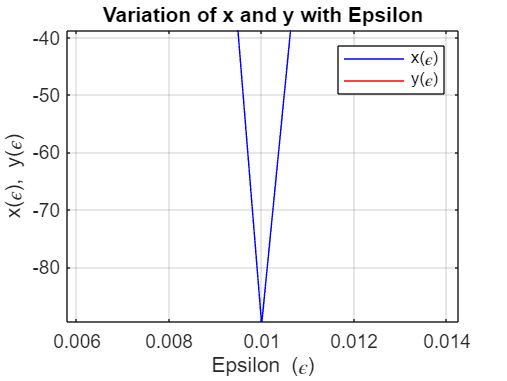

% Define the range of epsilon values
epsilon_values = 0:0.001:0.02;

% Initialize arrays to store x and y values
x_values = zeros(size(epsilon_values));
y_values = zeros(size(epsilon_values));

% Solve the system of equations for each epsilon
for i = 1:length(epsilon_values)
    epsilon = epsilon_values(i);
    
    % Calculate y(epsilon)
    y = (0.1 - epsilon * 11) / (1 - epsilon * 101);
    y_values(i) = y;
    
    % Calculate x(epsilon) using the expression x = 11 - 101y
    x = 11 - 101 * y;
    x_values(i) = x;
end

% Plot x(epsilon) and y(epsilon)
figure;
plot(epsilon_values, x_values, 'b', epsilon_values, y_values, 'r');
xlabel('Epsilon (\epsilon)');
ylabel('x(\epsilon), y(\epsilon)');
legend('x(\epsilon)', 'y(\epsilon)');
title('Variation of x and y with Epsilon');
grid on;